clear all 
close all 
clc
 
%question 3
theta=[linspace(0,360,17)];
theta_rad = theta*pi/180;
theta_rad2 =linspace(min(theta_rad),max(theta_rad),100);
vs = [0, 2.4, 9.3, 14.8, 17.8, 13.9, 7, 2, 0, 2.7, 8.1, 14.7, 17.8, 14.2, 7.2, 2.2, 0];
vs = vs * 1.2 % correction car olivier a tout fait bouger

vs =          0    2.8800   11.1600   17.7600   21.3600   16.6800    8.4000    2.4000         0    3.2400    9.7200   17.6400   21.3600   17.0400    8.6400    2.6400         0


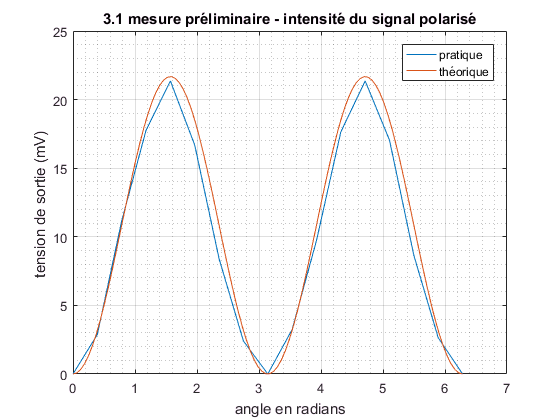

V0 = sqrt(5e-3 * 9.4*e4) ; %intensité optique du laser calculée à partir de la puissance du laser et de la résistance série interne
 
V_transmis = V0 * (sin(theta_rad2)).^2; %calcul théorique
figure(1)
plot (theta_rad,vs)
 
hold on 
plot (theta_rad2,V_transmis)
xlabel('angle en radians')
ylabel('tension de sortie (mV) ')
title(['3.1 mesure préliminaire - ' 'intensité du signal polarisé'])
grid
legend('pratique','théorique')
grid minor